# Лабораторна робота №2

Яковець А., варіант 15

**Апроксимація вибірки за допомогою M-функцій Curve Fitting Toolbox.**

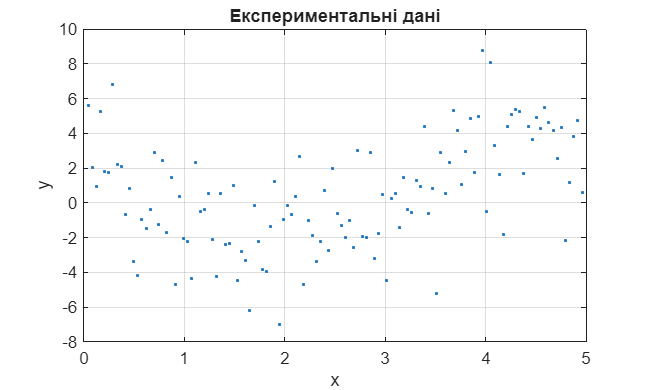

clear
clc
close all

fileName = 'v15.txt';
data = load(fileName);

x = data(:,1);
y = data(:,2);
figure
plot (x, y, '.', 'MarkerSize',5)
xlabel('x')
ylabel('y')
title('Експериментальні дані')
grid on

Підбір поліному

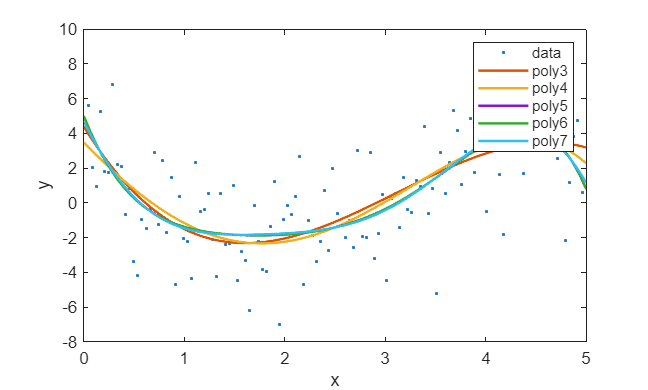

[f3,gof3] = fit(x,y,'poly3');
[f4,gof4] = fit(x,y,'poly4');
[f5,gof5] = fit(x,y,'poly5');
[f6,gof6] = fit(x,y,'poly6');
[f7,gof7] = fit(x,y,'poly7');
plot (x, y, '.', 'MarkerSize',5)
hold on
plot(f3)
plot(f4)
plot(f5)
plot(f6)
plot(f7)
legend('data','poly3','poly4','poly5','poly6','poly7')

Порівняєм (R^2 має прямувати до 1, середньоквадратична помилка та сума квадратів помилок мають бути найменші)

gof3.rsquare

ans = 0.4483

gof4.rsquare

ans = 0.4563

gof5.rsquare

ans = 0.4721

gof6.rsquare

ans = 0.4721

gof7.rsquare

ans = 0.4726

gof3.rmse

ans = 2.3792

gof4.rmse

ans = 2.3722

gof5.rmse

ans = 2.3476

gof6.rmse

ans = 2.3580

gof7.rmse

ans = 2.3674

gof3.sse

ans = 656.6288

gof4.sse

ans = 647.1560

gof5.sse

ans = 628.2926

gof6.sse

ans = 628.2869

gof7.sse

ans = 627.7303

Найраще підходить поліном 5 степеня

ft = fittype('poly5');
opts = fitoptions('Method','LinearLeastSquares');
[fresult, gof, output] = fit(x,y,ft,opts);

fresult

fresult =      Linear model Poly5:
     fresult(x) = p1*x^5 + p2*x^4 + p3*x^3 + p4*x^2 + p5*x + p6
     Coefficients (with 95% confidence bounds):
       p1 =     -0.1106  (-0.2289, 0.007826)
       p2 =       1.285  (-0.2027, 2.773)
       p3 =      -5.606  (-12.37, 1.155)
       p4 =       12.43  (-0.9703, 25.83)
       p5 =      -14.34  (-25.27, -3.413)
       p6 =       4.964  (2.219, 7.709)

gof

gof = struct with fields:
           sse: 628.2926
       rsquare: 0.4721
           dfe: 114
    adjrsquare: 0.4489
          rmse: 2.3476


output

output = struct with fields:
        numobs: 120
      numparam: 6
     residuals: [120×1 double]
      Jacobian: [120×6 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1


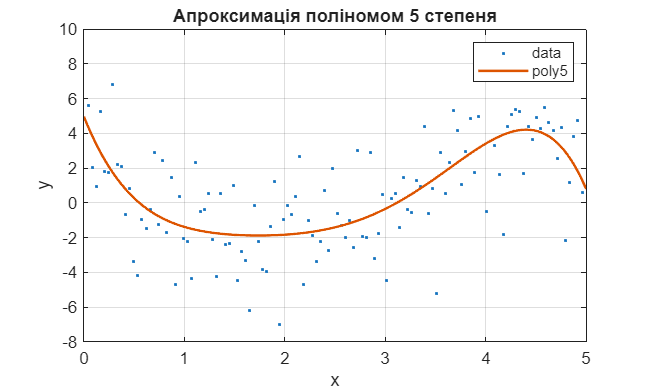


figure
plot(x, y, '.', 'MarkerSize',5)
hold on
plot(f5)
grid on
legend('data','poly5')
title('Апроксимація поліномом 5 степеня')
xlabel('x')
ylabel('y')

  Графік похибок

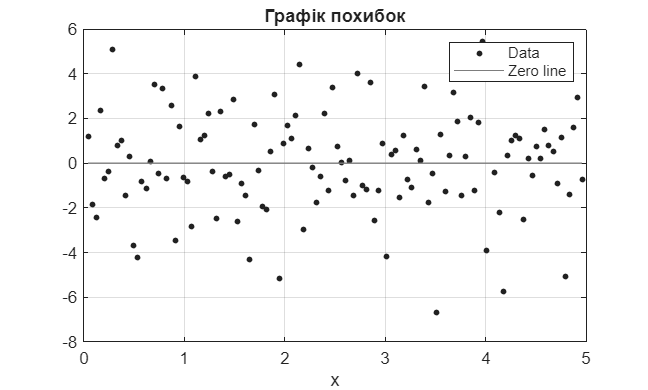

figure
plot(fresult,x,y,'residuals')
title('Графік похибок')
grid on


residual = output.residuals;

Графік похибок для кожної точки

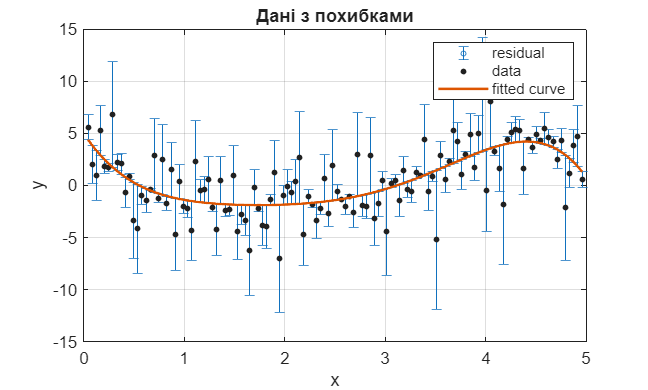

u = abs(residual);

figure
errorbar(x,y,u,'o','MarkerSize',3)

hold on
plot(fresult, x, y)

grid on
legend('residual','data','fitted curve')
title('Дані з похибками')

Коеф полінома

coef = coeffvalues(fresult)

coef =    -0.1106    1.2849   -5.6060   12.4290  -14.3403    4.9638


Гладший графік

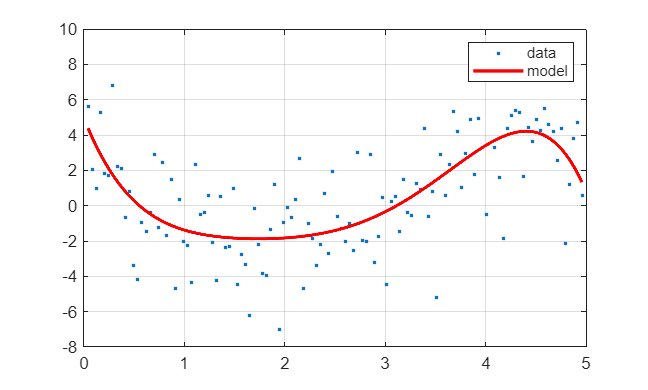

xx = x(1):0.001:x(end);

ff = feval(fresult,xx);

figure
plot(x,y,'.')
hold on
plot(xx,ff,'r','LineWidth',2)

grid on
legend('data','model')

Екстраполяція

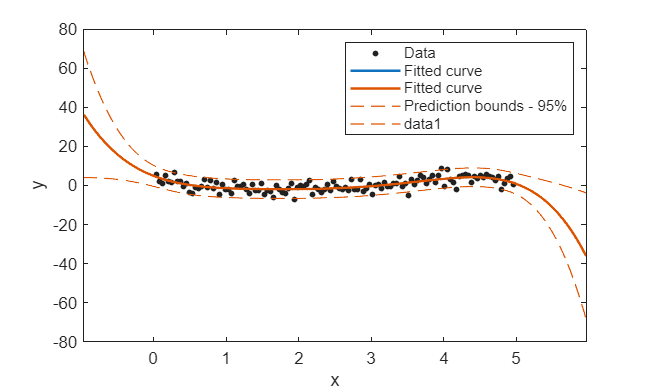

figure
plot(fresult,x,y)
xlim([min(x)-1 max(x)+1])
hold on
plot(fresult,'predobs')

**Апроксимація вибірки за допомогою користувацьких графічних інтерфейсів Curve Fitting Toolbox.**

cftool

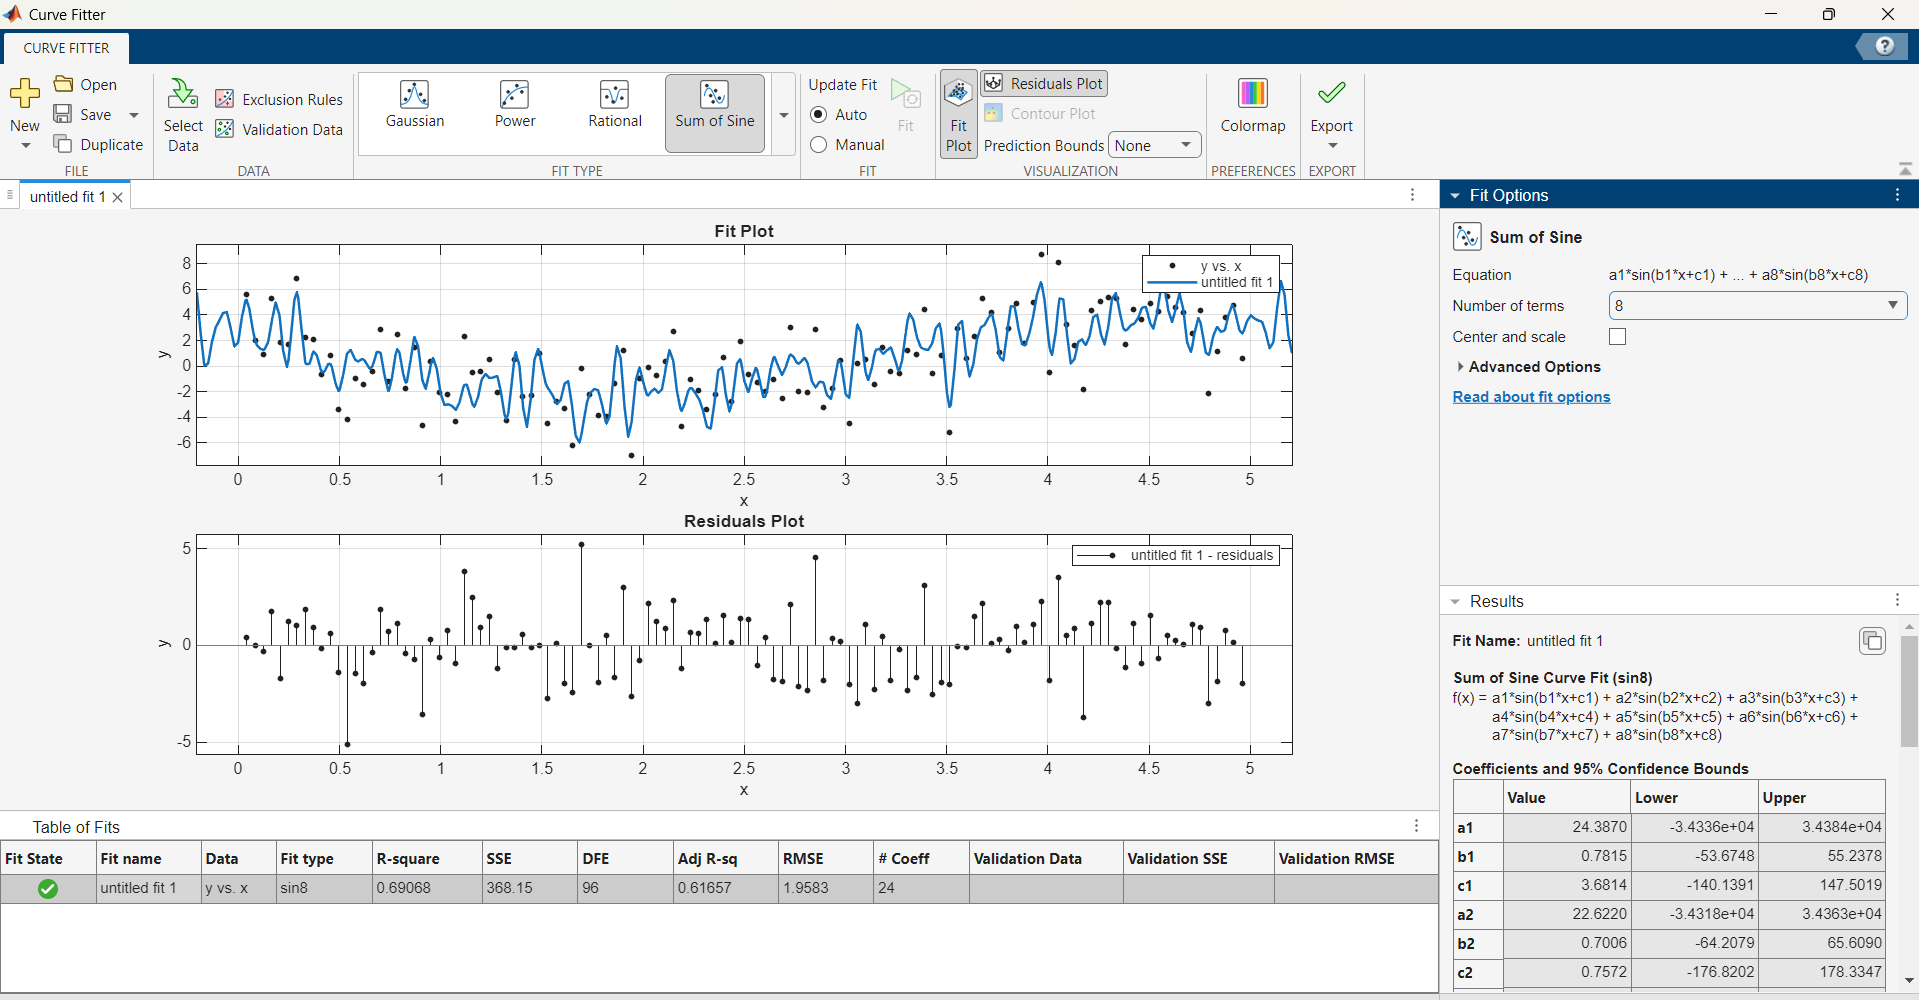

**Апроксимація вибірки у графічному вікні Property Editor.**

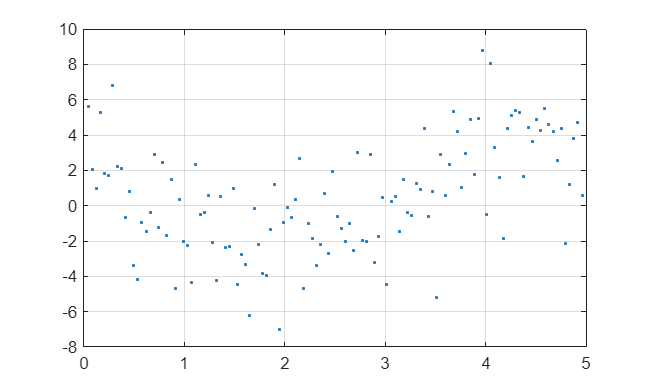

figure
plot(x,y,'.','MarkerSize',5)
grid on